a =    86.8879   80.7086   77.4611   74.8282   69.6411   81.0736   77.7809   82.2324   69.8042   89.2528   83.4104   69.0336   87.3994   75.8870   82.1156   81.5362   73.8526   59.9702   83.7489   77.6057   75.8150   82.9324   75.1722   84.6983   81.0563   73.0608   85.8578   83.3216   88.7652   73.7516   73.7331   82.1933   84.6692   85.7968   80.0456   78.3488   84.5697   93.7517   86.1921   80.5918   75.9784   83.4983   76.6113   81.6691   85.4477   86.4699   84.1170   89.6455   92.9584   66.7163


a =     60    66    67    68    69    69    70    70    70    71    73    73    73    74    74    74    74    74    74    74    75    75    75    76    76    76    77    77    77    77    77    77    78    78    78    78    78    78    79    79    79    79    79    79    80    80    80    80    80    80


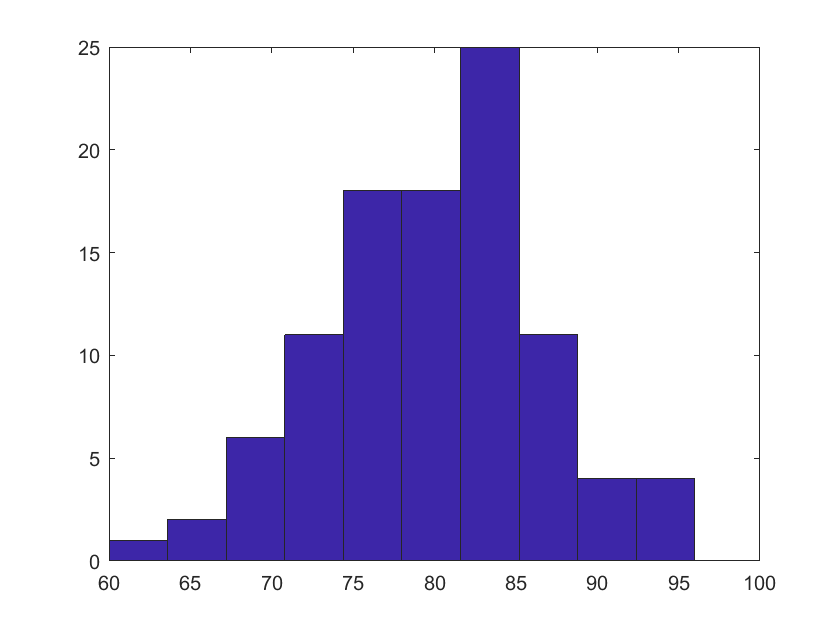

ans = 60

sc=0;


A=[a1' a2' a3' a4' a5' a6']*5;
if sc==1;A=a1;end
b=normrnd(78,9,[1 100])

b =    69.7936   78.4449   87.7024   80.7736   80.6967   76.2250   76.6822   77.0724   52.8092   81.5395   86.9122   66.3213   64.3023   83.5891   64.4323   62.8854   85.1008   72.1115   89.2041   66.3696   72.4708   80.1753   82.9441   82.2087   79.7231   75.9318   72.7870   82.3243   74.5185   81.7945   87.7894   57.7560   94.2403   72.3115   89.8481   91.9643   64.7798   79.5924  109.1963   76.0684   82.3765   80.9780   89.4111   87.8146   69.4819   74.0535   81.0890   77.4744  100.8148   81.9478


b=sort(round(b))

b =     52    53    58    62    62    63    63    64    64    65    65    65    66    66    66    68    68    69    69    70    70    70    71    71    71    72    72    72    72    73    73    73    73    74    74    74    74    75    76    76    76    76    76    76    77    77    77    77    78    78


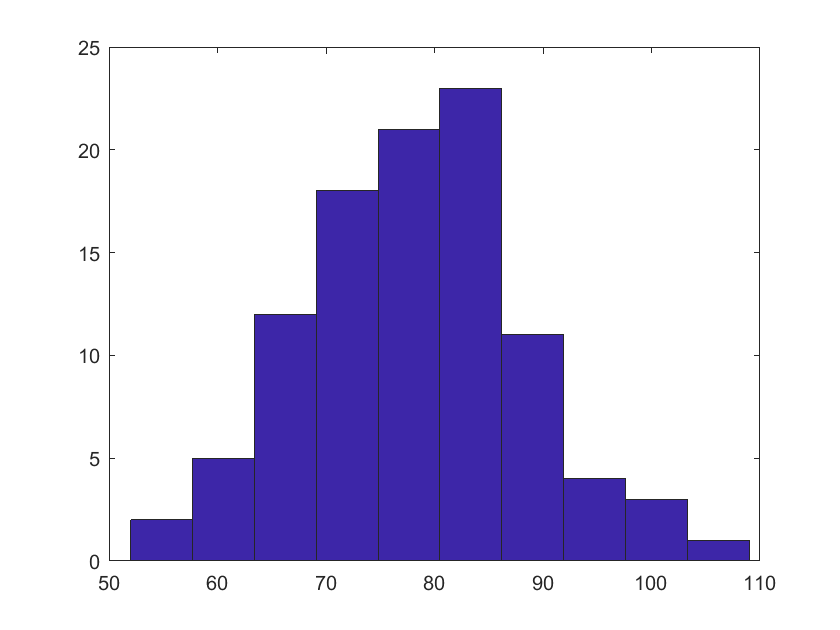

hist(b)

if sc==1;B=b;end
dX=mean(A)-mean(B)

dmean = 6.3300

% [h,pvalue,ci]=ttest(x,990);
t1=dX/sqrt((std(A)^2+std(B)^2)/length([A B]));

t1 = 5.9232

% t2=dmeanXY/sqrt((std(X)^2+std(Y)^2)/100);
save t1127 X Y A B
tell1=[mean(B) std(B) mean(A) std(A)];
% 频率图
xy1=ceil([A]*0.6/5)*5;
xy2=ceil([B]*0.6/5)*5;
tell2=[mean(xy2) std(xy2) mean(xy1) std(xy1) ]
dX2=mean(xy1)-mean(xy2)
t2=dX2/sqrt((std(xy1)^2+std(xy2)^2)/length([xy1 xy2]))

yx1=A-xy1;
yx2=B-xy2;
tell3=[mean(yx2) std(yx2) mean(yx1) std(yx1) ]
dX2=mean(yx1)-mean(yx2)
t3=dX2/sqrt((std(yx1)^2+std(yx2)^2)/length([yx1 yx2]))
% 数据导出
r=1;
tableA{r}=[A(1:length(a1));xy1(1:length(a1));yx1(1:length(a1))]';
f=length(tableA{r})+1;t=length(tableA{r})+length(a2);r=r+1;
tableA{r}=[A(f:t);xy1(f:t);yx1(f:t)]';
f=length(tableA{r})+1;t=length(tableA{r})+length(a3);r=r+1;
tableA{r}=[A(f:t);xy1(f:t);yx1(f:t)]';
f=length(tableA{r})+1;t=length(tableA{r})+length(a4);r=r+1;
tableA{r}=[A(f:t);xy1(f:t);yx1(f:t)]';
f=length(tableA{r})+1;t=length(tableA{r})+length(a5);r=r+1;
tableA{r}=[A(f:t);xy1(f:t);yx1(f:t)]';
f=length(tableA{r})+1;t=length(tableA{r})+length(a6);r=r+1;
tableA{r}=[A(f:t);xy1(f:t);yx1(f:t)]';
f = 1; t = length(b1); r = 1;
tableB{r} = [B(f:t);xy2(f:t);yx2(f:t)]';
f = length(tableB{r})+1; t = length(tableB{r})+length(b2); r = r+1; 
tableB{r} = [B(f:t);xy2(f:t);yx2(f:t)]';
f = length(tableB{r})+1; t = length(tableB{r})+length(b2); r = r+1; 
tableB{r} = [B(f:t);xy2(f:t);yx2(f:t)]';
